# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'kinovaGen3';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "EndEffector_Link"; 

Specify initial and desired end-effector poses. Use inverse kinematics to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([-3 2 -3 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([3 2 3 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

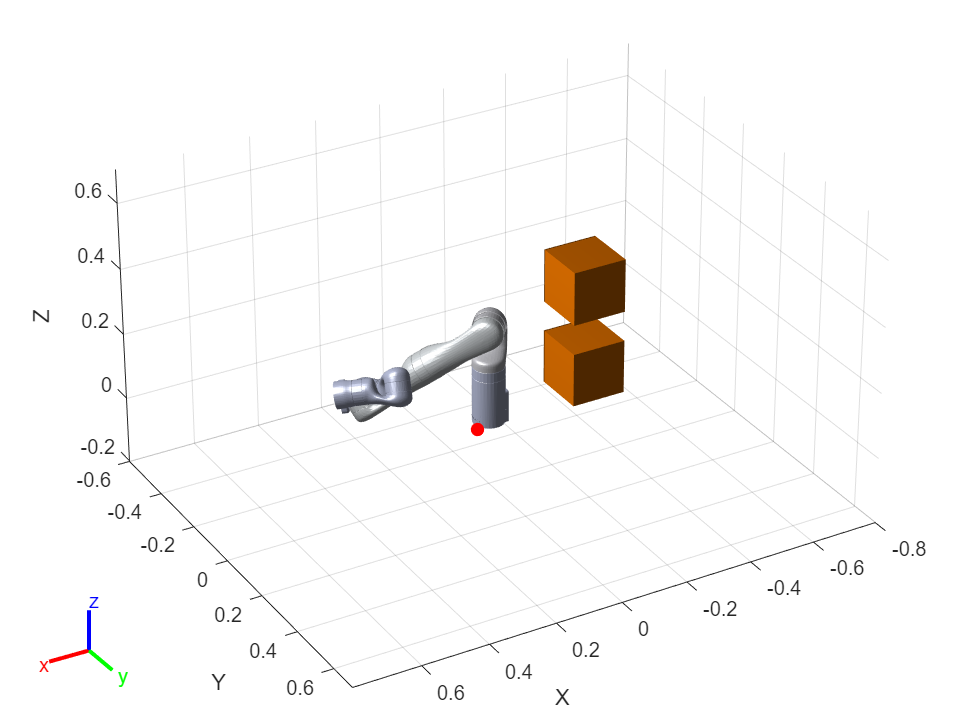

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

iter = 1

Elapsed time is 3.313912 seconds.


Qtheta = 737.1590

RAR = 223.1415

iter = 2

Elapsed time is 3.289804 seconds.


Qtheta = 749.8541

RAR = 223.1480

iter = 3

Elapsed time is 3.442137 seconds.


Qtheta = 737.3875

RAR = 223.1552

iter = 4

Elapsed time is 3.302104 seconds.


Qtheta = 739.3207

RAR = 223.1586

iter = 5

Elapsed time is 3.206767 seconds.


Qtheta = 731.6247

RAR = 223.1720

iter = 6

Elapsed time is 3.255371 seconds.


Qtheta = 723.0198

RAR = 223.1786

iter = 7

Elapsed time is 3.208197 seconds.


Qtheta = 746.2755

RAR = 223.1736

iter = 8

Elapsed time is 3.161121 seconds.


Qtheta = 734.6945

RAR = 223.1808

iter = 9

Elapsed time is 3.168420 seconds.


Qtheta = 740.7790

RAR = 223.1791

iter = 10

Elapsed time is 3.209676 seconds.


Qtheta = 722.8393

RAR = 223.1859

iter = 11

Elapsed time is 3.163042 seconds.


Qtheta = 722.6650

RAR = 223.1884

iter = 12

Elapsed time is 3.200229 seconds.


Qtheta = 701.5728

RAR = 223.1845

iter = 13

Elapsed time is 3.226757 seconds.


Qtheta = 689.5186

RAR = 223.1895

iter = 14

Elapsed time is 3.194160 seconds.


Qtheta = 701.0224

RAR = 223.1927

iter = 15

Elapsed time is 3.328187 seconds.


Qtheta = 691.6065

RAR = 223.1993

iter = 16

Elapsed time is 3.231685 seconds.


Qtheta = 702.7659

RAR = 223.2059

iter = 17

Elapsed time is 3.175526 seconds.


Qtheta = 683.4231

RAR = 223.2039

iter = 18

Elapsed time is 3.154245 seconds.


Qtheta = 673.1426

RAR = 223.2077

iter = 19

Elapsed time is 3.196609 seconds.


Qtheta = 676.0790

RAR = 223.2149

iter = 20

Elapsed time is 3.183891 seconds.


Qtheta = 678.9297

RAR = 223.2153

iter = 21

Elapsed time is 3.258876 seconds.


Qtheta = 682.0159

RAR = 223.2130

iter = 22

Elapsed time is 3.192903 seconds.


Qtheta = 671.7315

RAR = 223.2130

iter = 23

Elapsed time is 3.232611 seconds.


Qtheta = 676.6406

RAR = 223.2116

iter = 24

Elapsed time is 3.148976 seconds.


Qtheta = 679.0272

RAR = 223.2127

iter = 25

Elapsed time is 3.150511 seconds.


Qtheta = 665.8616

RAR = 223.2170

iter = 26

Elapsed time is 3.174481 seconds.


Qtheta = 630.5571

RAR = 223.2142

iter = 27

Elapsed time is 3.215813 seconds.


Qtheta = 642.1430

RAR = 223.2247

iter = 28

Elapsed time is 3.212181 seconds.


Qtheta = 633.4496

RAR = 223.2268

iter = 29

Elapsed time is 3.207796 seconds.


Qtheta = 648.4305

RAR = 223.2264

iter = 30

Elapsed time is 3.224346 seconds.


Qtheta = 629.2316

RAR = 223.2300

iter = 31

Elapsed time is 3.228849 seconds.


Qtheta = 624.0489

RAR = 223.2361

iter = 32

Elapsed time is 3.221818 seconds.


Qtheta = 638.5844

RAR = 223.2416

iter = 33

Elapsed time is 3.204802 seconds.


Qtheta = 639.1636

RAR = 223.2434

iter = 34

Elapsed time is 3.205623 seconds.


Qtheta = 642.4146

RAR = 223.2467

iter = 35

Elapsed time is 3.248770 seconds.


Qtheta = 644.6126

RAR = 223.2439

iter = 36

Elapsed time is 3.231169 seconds.


Qtheta = 623.3566

RAR = 223.2447

iter = 37

Elapsed time is 3.247810 seconds.


Qtheta = 611.5444

RAR = 223.2409

iter = 38

Elapsed time is 3.213983 seconds.


Qtheta = 612.2002

RAR = 223.2419

iter = 39

Elapsed time is 3.215731 seconds.


Qtheta = 622.1100

RAR = 223.2412

iter = 40

Elapsed time is 3.220316 seconds.


Qtheta = 610.2168

RAR = 223.2473

iter = 41

Elapsed time is 3.215997 seconds.


Qtheta = 611.4922

RAR = 223.2474

iter = 42

Elapsed time is 3.191402 seconds.


Qtheta = 607.2099

RAR = 223.2515

iter = 43

Elapsed time is 3.212746 seconds.


Qtheta = 598.4144

RAR = 223.2501

iter = 44

Elapsed time is 3.182244 seconds.


Qtheta = 601.4498

RAR = 223.2504

iter = 45

Elapsed time is 3.263066 seconds.


Qtheta = 590.0642

RAR = 223.2398

iter = 46

Elapsed time is 3.277066 seconds.


Qtheta = 590.8774

RAR = 223.2399

iter = 47

Elapsed time is 3.218154 seconds.


Qtheta = 588.7642

RAR = 223.2371

iter = 48

Elapsed time is 3.212976 seconds.


Qtheta = 568.7281

RAR = 223.2398

iter = 49

Elapsed time is 3.207353 seconds.


Qtheta = 568.3059

RAR = 223.2419

iter = 50

Elapsed time is 3.208774 seconds.


Qtheta = 592.6262

RAR = 223.2361

iter = 51

Elapsed time is 3.209103 seconds.


Qtheta = 575.2628

RAR = 223.2362

iter = 52

Elapsed time is 3.203564 seconds.


Qtheta = 578.1708

RAR = 223.2338

iter = 53

Elapsed time is 3.203607 seconds.


Qtheta = 572.7865

RAR = 223.2310

iter = 54

Elapsed time is 3.203999 seconds.


Qtheta = 566.4503

RAR = 223.2336

iter = 55

Elapsed time is 3.207777 seconds.


Qtheta = 551.9792

RAR = 223.2307

iter = 56

Elapsed time is 3.201939 seconds.


Qtheta = 545.1256

RAR = 223.2265

iter = 57

Elapsed time is 3.200106 seconds.


Qtheta = 534.2785

RAR = 223.2202

iter = 58

Elapsed time is 3.202572 seconds.


Qtheta = 540.3587

RAR = 223.2192

iter = 59

Elapsed time is 3.223547 seconds.


Qtheta = 536.1728

RAR = 223.2173

iter = 60

Elapsed time is 3.219380 seconds.


Qtheta = 535.1167

RAR = 223.2191

iter = 61

Elapsed time is 3.205623 seconds.


Qtheta = 541.9946

RAR = 223.2199

iter = 62

Elapsed time is 3.244308 seconds.


Qtheta = 538.7526

RAR = 223.2162

iter = 63

Elapsed time is 3.257663 seconds.


Qtheta = 540.7769

RAR = 223.2104

iter = 64

Elapsed time is 3.237411 seconds.


Qtheta = 534.7482

RAR = 223.2136

iter = 65

Elapsed time is 3.160969 seconds.


Qtheta = 537.2003

RAR = 223.2145

iter = 66

Elapsed time is 3.203051 seconds.


Qtheta = 516.1396

RAR = 223.2102

iter = 67

Elapsed time is 3.229819 seconds.


Qtheta = 517.8098

RAR = 223.2095

iter = 68

Elapsed time is 3.255893 seconds.


Qtheta = 516.2226

RAR = 223.2135

iter = 69

Elapsed time is 3.201716 seconds.


Qtheta = 509.8472

RAR = 223.2183

iter = 70

Elapsed time is 3.272848 seconds.


Qtheta = 497.9833

RAR = 223.2202

iter = 71

Elapsed time is 3.267806 seconds.


Qtheta = 498.5780

RAR = 223.2221

iter = 72

Elapsed time is 3.256663 seconds.


Qtheta = 497.7995

RAR = 223.2217

iter = 73

Elapsed time is 3.195192 seconds.


Qtheta = 498.8424

RAR = 223.2198

iter = 74

Elapsed time is 3.198702 seconds.


Qtheta = 500.5485

RAR = 223.2244

iter = 75

Elapsed time is 3.153009 seconds.


Qtheta = 501.5458

RAR = 223.2235

iter = 76

Elapsed time is 3.195572 seconds.


Qtheta = 500.0496

RAR = 223.2239

iter = 77

Elapsed time is 3.213888 seconds.


Qtheta = 502.8085

RAR = 223.2226

iter = 78

Elapsed time is 3.218794 seconds.


Qtheta = 494.7649

RAR = 223.2198

iter = 79

Elapsed time is 3.219829 seconds.


Qtheta = 493.8976

RAR = 223.2248

iter = 80

Elapsed time is 3.196303 seconds.


Qtheta = 492.8012

RAR = 223.2231

iter = 81

Elapsed time is 3.226946 seconds.


Qtheta = 484.0834

RAR = 223.2243

iter = 82

Elapsed time is 3.182387 seconds.


Qtheta = 489.0432

RAR = 223.2277

iter = 83

Elapsed time is 3.176489 seconds.


Qtheta = 484.0119

RAR = 223.2304

iter = 84

Elapsed time is 3.158106 seconds.


Qtheta = 468.6608

RAR = 223.2273

iter = 85

Elapsed time is 3.185071 seconds.


Qtheta = 469.5980

RAR = 223.2295

iter = 86

Elapsed time is 3.190980 seconds.


Qtheta = 477.0246

RAR = 223.2316

iter = 87

Elapsed time is 3.143581 seconds.


Qtheta = 469.6639

RAR = 223.2234

iter = 88

Elapsed time is 3.141951 seconds.


Qtheta = 463.2382

RAR = 223.2225

iter = 89

Elapsed time is 3.178138 seconds.


Qtheta = 461.8602

RAR = 223.2222

iter = 90

Elapsed time is 3.132454 seconds.


Qtheta = 458.3503

RAR = 223.2232

iter = 91

Elapsed time is 3.191242 seconds.


Qtheta = 457.3124

RAR = 223.2196

iter = 92

Elapsed time is 3.182341 seconds.


Qtheta = 452.7383

RAR = 223.2189

iter = 93

Elapsed time is 3.202031 seconds.


Qtheta = 454.1096

RAR = 223.2184

iter = 94

Elapsed time is 3.166374 seconds.


Qtheta = 459.2491

RAR = 223.2185

iter = 95

Elapsed time is 3.219580 seconds.


Qtheta = 456.0026

RAR = 223.2152

iter = 96

Elapsed time is 3.168586 seconds.


Qtheta = 446.8255

RAR = 223.2144

iter = 97

Elapsed time is 3.181746 seconds.


Qtheta = 449.8791

RAR = 223.2156

iter = 98

Elapsed time is 3.205907 seconds.


Qtheta = 451.0193

RAR = 223.2150

iter = 99

Elapsed time is 3.214269 seconds.


Qtheta = 456.6939

RAR = 223.2151

iter = 100

Elapsed time is 3.159284 seconds.


Qtheta = 447.4420

RAR = 223.2137

iter = 101

Elapsed time is 3.186581 seconds.


Qtheta = 452.3292

RAR = 223.2102

Maximum iteration (30) has reached.
STOMP Finished.


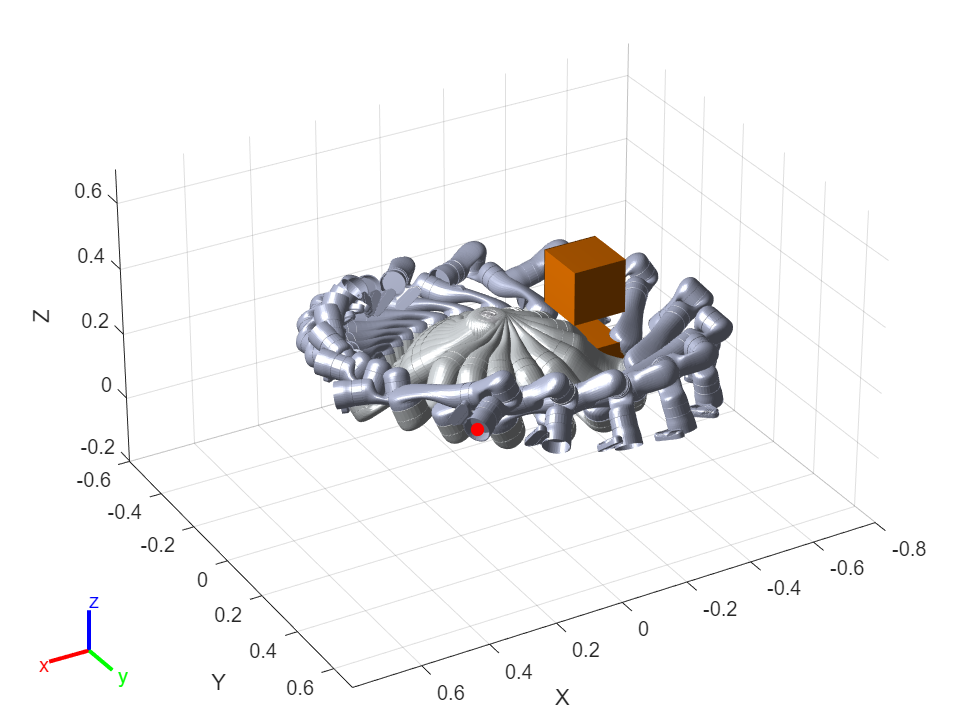

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.